## **CELL ATTACHED DATA**


colo = [.1, .3, .7];
colo2 = [.68, .1, .2];

col_exc = [1 0 1];
col_inh = [0 1 1];
    

set(0,'DefaultAxesFontSize',14)


## Population stats for WFDS ON

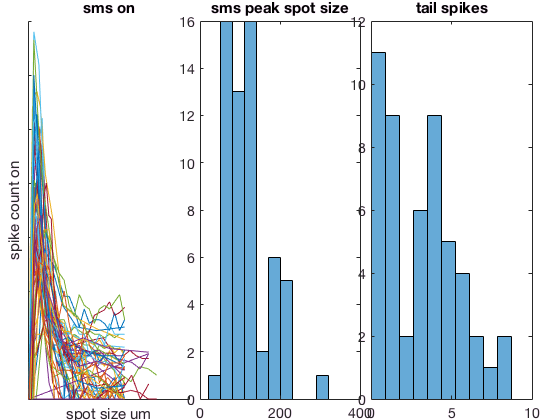

% spots multiple sizes

figure(101);clf;
handles = tight_subplot(1,3);
peakSize = [];
tailSpikes = [];
axes(handles(1));
for ci = 1:size(dtab,1)
    if ~selectWfdsOn(ci)
        continue
    end
    spotSize = dtab{ci, 'SMS_spotSize_ca'}{1};
    if ~isempty(spotSize)
        spikes = dtab{ci, 'SMS_onSpikes'}{1};
        hold on
        plot(spotSize, spikes);
        [m, mi] = max(spikes);
        peakSize(ci) = spotSize(mi);
        tailSpikes(ci) = mean(spikes(end-2:end));
    end
end
xlabel('spot size um')
ylabel('spike count on')
title('sms on')
hold off

axes(handles(2));
peakSize(peakSize == 0) = nan;
histogram(peakSize, 10)
title('sms peak spot size')

axes(handles(3));
tailSpikes(tailSpikes == 0) = nan;
histogram(tailSpikes, 10)
title('tail spikes')

## Population stats for WFDS OFF

% spots multiple sizes

figure(101);clf;
handles = tight_subplot(1,3);
peakSize = [];
tailSpikes = [];
axes(handles(1));
for ci = 1:size(dtab,1)
    if ~selectWfdsOff(ci)
        continue
    end
    spotSize = dtab{ci, 'SMS_spotSize_ca'}{1};
    if ~isempty(spotSize)
        spikes = dtab{ci, 'SMS_offSpikes'}{1};
        hold on
        plot(spotSize, spikes);
        [m, mi] = max(spikes);
        peakSize(ci) = spotSize(mi);
        tailSpikes(ci) = mean(spikes(end-2:end));
    end
end
xlabel('spot size um')
ylabel('spike count off')
title('sms off')
hold off

axes(handles(2));
peakSize(peakSize == 0) = nan;
histogram(peakSize, 10)
title('sms peak spot size')

axes(handles(3));
tailSpikes(tailSpikes == 0) = nan;
histogram(tailSpikes, 10)
title('tail spikes')

## light step

figure(111)
subplot(1,2,1)
histogram(dtab{selectWfdsOn,'LS_ON_sp'},'Normalization','pdf')
hold on
histogram(dtab{selectWfdsOff,'LS_ON_sp'}, 'Normalization','pdf')
histogram(dtab{selectControl,'LS_ON_sp'}, 'Normalization','pdf')
hold off
legend('ON','OFF','other');
title('ls on spikes')

subplot(1,2,2)
histogram(dtab{selectWfdsOn,'LS_OFF_sp'}, 'Normalization','pdf')
hold on
histogram(dtab{selectWfdsOff,'LS_OFF_sp'}, 'Normalization','pdf')
histogram(dtab{selectControl,'LS_OFF_sp'}, 'Normalization','pdf')
hold off
legend('ON','OFF','other');
title('ls off spikes')

## calculate the best DS

src = {'DrifTex_DSI_sp','DrifGrat_DSI_sp','MB_1000_DSI_sp','MB_500_DSI_sp','MB_250_DSI_sp'};
for ci = 1:numCells
    dsis = dtab{ci, {'DrifTex_DSI_sp','DrifGrat_DSI_sp','MB_1000_DSI_sp','MB_500_DSI_sp','MB_250_DSI_sp'}};
    angs = dtab{ci, {'DrifTex_DSang_sp','DrifGrat_DSang_sp','MB_1000_DSang_sp','MB_500_DSang_sp','MB_250_DSang_sp'}};
    [m, i] = max(dsis);
    dtab{ci,'best_DSI_sp'} = m;
    dtab{ci,'best_DSang_sp'} = angs(i);
    dtab{ci,'best_source'} = {src{i}};
end

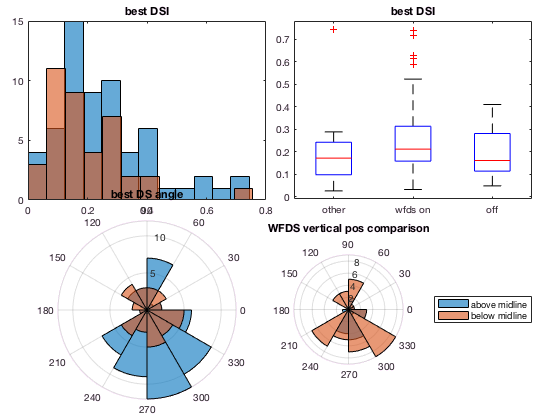

    
%
    
figure(121);clf;
handles = tight_subplot(2, 2, .05, .05);

axes(handles(1));
histogram(dtab{selectWfdsOn,'best_DSI_sp'}, 12)
hold on
histogram(dtab{~selectWfdsOn,'best_DSI_sp'}, 12)
hold off
title('best DSI')

axes(handles(2));
boxplot(dtab{:,'best_DSI_sp'}, selectWfdsOn + 2 * selectWfdsOff, 'Labels',{'other','wfds on', 'off'})
title('best DSI')

axes(handles(3));
polarhistogram(deg2rad(dtab{selectWfdsOn,'best_DSang_sp'}), 12)
hold on
polarhistogram(deg2rad(dtab{~selectWfdsOn,'best_DSang_sp'}), 12)
hold off
title('best DS angle')

axes(handles(4));
above = dtab{:, 'location_y'} > 0;
polarhistogram(deg2rad(dtab{selectWfdsOn & above,'best_DSang_sp'}), 12)
hold on
polarhistogram(deg2rad(dtab{selectWfdsOn & ~above,'best_DSang_sp'}), 12)
hold off
title('WFDS vertical pos comparison')
legend('above midline','below midline');

angles = dtab{:,'best_DSang_sp'};

## Moving Bar DSI

figure(125);clf
handles = tight_subplot(3, 2, .05, .05);


axes(handles(1));
histogram(dtab{selectWfdsOn,'MB_1000_DSI_sp'}, 12)
title('MB 1000 DSI')

axes(handles(2));
polarhistogram(deg2rad(dtab{selectWfdsOn,'MB_1000_DSang_sp'}), 12)
title('MB 1000 DS angle')

axes(handles(3));
histogram(dtab{selectWfdsOn,'MB_500_DSI_sp'}, 12)
title('MB 500 DSI')

axes(handles(4));
polarhistogram(deg2rad(dtab{selectWfdsOn,'MB_500_DSang_sp'}), 12)
title('MB 500 DS angle')

axes(handles(5));
histogram(dtab{selectWfdsOn,'MB_250_DSI_sp'}, 12)
title('MB 250 DSI')

axes(handles(6));
polarhistogram(deg2rad(dtab{selectWfdsOn,'MB_250_DSang_sp'}), 12)
title('MB 250 DS angle')

## DSI over speed

figure(126);clf
handles = tight_subplot(1, 2, .05, .1, .1);

axes(handles(1));
for i = 1:numCells
    plot([250, 500, 1000],dtab{i,{'MB_250_DSI_sp', 'MB_500_DSI_sp', 'MB_1000_DSI_sp'}})
    hold on
end
xlabel('speed')
ylabel('DSI')
hold off

axes(handles(2));
plot(dtab{selectWfdsOn,'MB_1000_DSI_sp'} .* exp(sqrt(-1) * deg2rad(dtab{selectWfdsOn,'MB_1000_DSang_sp'})), 'o')
hold on
plot(dtab{selectWfdsOn,'MB_500_DSI_sp'} .* exp(sqrt(-1) * deg2rad(dtab{selectWfdsOn,'MB_500_DSang_sp'})), 'o')
plot(dtab{selectWfdsOn,'MB_250_DSI_sp'} .* exp(sqrt(-1) * deg2rad(dtab{selectWfdsOn,'MB_250_DSang_sp'})), 'o')
title('DS (index and direction)')
legend('1000','500','250')

line([-.5,.5],[0,0])
line([0,0],[-.5,.5])
axis equal

## spatial RF offset

figure(131);clf;
handles = tight_subplot(3,3, .05, .1);
% angleOffset = zeros(length(cellNames),1);
% for i = 1:length(cellNames)
%     if ~isempty(strfind(cellNames{i}, 'B'))
%         angleOffset(i) = 270;
%     else
%         angleOffset(i) = 180;
%     end
% end
% angleOffset = deg2rad(angleOffset);

diffX = dtab.spatial_ex_centerX - dtab.spatial_in_centerX;
diffY = dtab.spatial_ex_centerY - dtab.spatial_in_centerY;
avgSigma = mean(dtab{:,{'spatial_in_sigma2X','spatial_ex_sigma2X','spatial_in_sigma2Y','spatial_ex_sigma2Y'}}, 2);
autocenterOffsetDistance = sqrt(diffX.^2 + diffY.^2);
autocenterOffsetDistanceNormalized = autocenterOffsetDistance ./ avgSigma;
autocenterOffsetDirections = angle(diffX + sqrt(-1) * diffY);
dtab.spatial_exin_offset = autocenterOffsetDistance .* exp(sqrt(-1) * autocenterOffsetDirections);

axes(handles(1));
plot(autocenterOffsetDistance(selectWfdsOn) .* exp(sqrt(-1) * autocenterOffsetDirections(selectWfdsOn)), 'ob')
hold on
plot(autocenterOffsetDistance(~selectWfdsOn) .* exp(sqrt(-1) * autocenterOffsetDirections(~selectWfdsOn)), 'or')
hold off
line([-10,10],[0,0])
line([0,0],[-10,10])
axis square
title('spatial offset Ex from In')
legend('WFDS','Other')

axes(handles(2));
plot(autocenterOffsetDistanceNormalized(selectWfdsOn) .* exp(sqrt(-1) * autocenterOffsetDirections(selectWfdsOn)), 'ob')
hold on
plot(autocenterOffsetDistanceNormalized(~selectWfdsOn) .* exp(sqrt(-1) * autocenterOffsetDirections(~selectWfdsOn)), 'or')
hold off
line([-1,1],[0,0])
line([0,0],[-1,1])
axis square
title('spatial offset Ex from In (norm)')
legend('WFDS','Other')


axes(handles(3));
boxplot(autocenterOffsetDistance, selectWfdsOn, 'Labels',{'other','wfds'})
% histogram(autocenterOffsetDistance(selectWfds), 10)
% hold on
% histogram(autocenterOffsetDistance(~selectWfds), 10)
% hold off
% xlabel('offset um')
title('magnitude of spatial offset')
% legend('WFDS','Other')

axes(handles(4));
boxplot(autocenterOffsetDistanceNormalized, selectWfdsOn, 'Labels',{'other','wfds'})
title('magnitude of spatial offset (norm)')


axes(handles(5));
polarhistogram(autocenterOffsetDirections(selectWfdsOn), 10)
hold on
polarhistogram(autocenterOffsetDirections(~selectWfdsOn), 10)
hold off
title('angle of spatial offset')

axes(handles(6));
spatialToTextureDiff = dtab.best_DSang_sp - rad2deg(autocenterOffsetDirections);
polarhistogram(deg2rad(spatialToTextureDiff(selectWfdsOn)), 10)
hold on
polarhistogram(deg2rad(spatialToTextureDiff(~selectWfdsOn)), 10)
title('difference between tex angle and offset angle')

spatialToImageDiff = mod(autocenterOffsetDirections(selectWfdsOn) - dtab.imageAngle(selectWfdsOn), 360);
axes(handles(7));
polarhistogram(deg2rad(spatialToImageDiff), 10)
title('difference between image angle and offset angle')


axes(handles(8));
plot(autocenterOffsetDistanceNormalized(selectWfdsOn), dtab{selectWfdsOn,'best_DSI_sp'}, 'o')
hold on
plot(autocenterOffsetDistanceNormalized(~selectWfdsOn), dtab{~selectWfdsOn,'best_DSI_sp'}, 'o')
hold off
title('Offset vs DSI')
xlabel('offset distance normalized')
ylabel('DSI')
line([0,1],[0,0])
line([0,0],[0,.6])

## Cell location analysis

figure(141);clf
ha = tight_subplot(2,3);

axes(ha(1))
plot(dtab{selectWfdsOn,'location_x'}, dtab{selectWfdsOn,'location_y'},'o')
line([-100,100],[0,0])
line([0,0],[-100,100])
axis(1.2*[-2000,2000, -2000,2000])
axis square
title('all wfds locations')

map_data = dtab{selectWfdsOn, {'location_x','location_y','best_DSang_sp','best_DSI_sp','eye','imageAngle'}};

% map_data: X, Y, angle, DSI, right=1
map_data(map_data(:,1) == 0 & map_data(:,2) == 0, :) = [];

x = -1*map_data(:,1); % compensate for rig spatial flip in dimension (negative right)
y = map_data(:,2);
ang = map_data(:,3);
mag = map_data(:,4);
left = map_data(:,5) == -1;
right = map_data(:,5) == 1;
u = mag .* cosd(ang);
v = mag .* sind(ang);

% Together
axes(ha(2));
x_eyesTogether = x;
x_eyesTogether(right) = -1 * x_eyesTogether(right);
uRigFlipped = u;
uRigFlipped(right) = -1 * uRigFlipped(right);
sel = left == 1;
quiver(x_eyesTogether(sel),y(sel),uRigFlipped(sel),v(sel),1.3,'color','red','linewidth',2)
hold on
sel = right == 1;
quiver(x_eyesTogether(sel),y(sel),uRigFlipped(sel),v(sel),1.3,'color','blue','linewidth',2)
legend('left','right');
line([-500, 500],[0,0],'color','k')
line([0,0],[-500, 500],'color','k')
axis(1.2*[-2000,2000, -2000,2000])
axis square
title('Both eyes')
xlabel('Nasal -- Caudal')

% left
axes(ha(3));
sel = left == 1;
quiver(x(sel),y(sel),u(sel),v(sel),1.3,'color','red','linewidth',2)
line([-500, 500],[0,0],'color','k')
line([0,0],[-500, 500],'color','k')
axis(1.2*[-2000,2000, -2000,2000])
axis square
title('Left')
xlabel('Nasal -- Caudal')

% right
axes(ha(4));
sel = right == 1;
quiver(x(sel),y(sel),u(sel),v(sel),1.3,'color','red','linewidth',2)
line([-500, 500],[0,0],'color','k')
line([0,0],[-500, 500],'color','k')
axis(1.2*[-2000,2000, -2000,2000])
axis square
title('Right')
xlabel('Caudal -- Nasal')


% Image angle
ang = map_data(:,6);
u = cosd(ang);
v = sind(ang);
axes(ha(5));
quiver(x,y,u,v)
title('image angles')
axis(1.2*[-2000,2000, -2000,2000])
axis square

% Autocenter offset angle
ang = rad2deg(autocenterOffsetDirections(selectWfdsOn));
u = autocenterOffsetDistance(selectWfdsOn) .* cosd(ang);
v = autocenterOffsetDistance(selectWfdsOn) .* sind(ang);
axes(ha(6));
quiver(x,y,u,v,2)
title('autocenter offset angles')
axis(1.2*[-2000,2000, -2000,2000])
axis square

## LIGHT STEP

figure(100);clf

histogram(dtab{selectWfds,'LS_ON_sp'}, 12, 'Normalization','pdf', 'FaceColor', colo)
hold on
histogram(dtab{:,'LS_OFF_sp'}, 10,'Normalization','pdf', 'FaceColor', colo2)
hold off
xlabel('Spike count') 
ylabel('PDF across cells')
title('Light Step Spike Counts')
legend({'Onset','Offset'})

## SPOTS MULTI SIZE

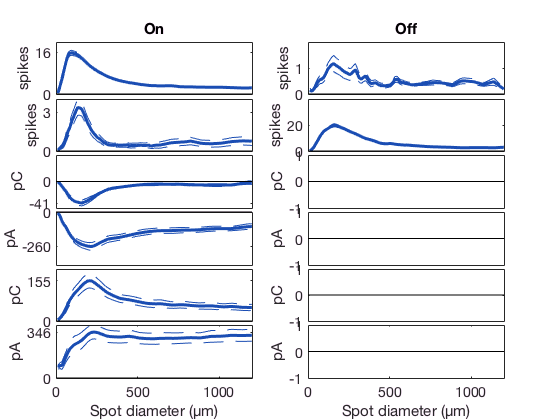

figure(102);clf;
peakSize = [];
tailSpikes = [];
spikesOverBaselineByVar = {};

varsToMean = {'SMS_onSpikes','SMS_offSpikes','SMS_charge_ex','SMS_peak_ex','SMS_charge_inh','SMS_peak_inh'};
ylabels = {'spikes','spikes','pC','pA','pC','pA'};
baselinesToMean = {'SMS_spotSize_ca','SMS_spotSize_ca','SMS_spotSize_exc','SMS_spotSize_exc','SMS_spotSize_inh','SMS_spotSize_inh'};

handles = tight_subplot(length(varsToMean), 2, [0.01, .1], 0.1, .1);
% tight_subplot(Nh, Nw, gap, marg_h, marg_w)

mean_spotSize = linspace(0,1199);

for vari = 1:length(varsToMean)
    cellCount = 0;
    
    for cellTypeIndex = 1:2
        spikesOverSpotSize = [];
        
        selects = {selectWfdsOn, selectWfdsOff};
        
        for ci = 1:numCells
            sel = selects{cellTypeIndex};
            if ~sel(ci)
                continue
            end
            spotSize = dtab{ci, baselinesToMean{vari}}{1};
            
            if ~isempty(spotSize)
                cellCount = cellCount + 1;
                spikes = dtab{ci, varsToMean{vari}}{1};
                % make mean spikes for each size due to repeat epochs
                unique_sizes = unique(spotSize);
                averagedOverRepeats = zeros(size(unique_sizes));
                for si = 1:length(unique_sizes)
                    averagedOverRepeats(si) = mean(spikes(spotSize == unique_sizes(si)));
                end
                       
        %         hold on
        %         plot(spotSize, spikes);
                [maxx, mi] = max(spikes);
                peakSize(ci) = spotSize(mi);
                tailSpikes(ci) = mean(spikes(end-2:end));
                
                % add to average
                spikesOverSpotSize(end+1,:) = interp1(unique_sizes, averagedOverRepeats, mean_spotSize);
            end
        end
        spikesOverBaselineByVar{cellTypeIndex, vari} = spikesOverSpotSize;
    
        i = (vari-1) * 2 + cellTypeIndex;
        axes(handles(i));
        m = nanmean(spikesOverBaselineByVar{cellTypeIndex, vari});
        s = nanstd(spikesOverBaselineByVar{cellTypeIndex, vari}) / sqrt(cellCount);
        plot(mean_spotSize, m, 'r', 'LineWidth',3, 'Color', colo)
        hold on
        plot(mean_spotSize, m+s, '--', 'Color', colo)
        plot(mean_spotSize, m-s, '--', 'Color', colo)
        line([0,1200],[0,0],'Color','k')
        
        if vari < length(varsToMean)
            xticks([])
        end
        
        [~, i] = max(abs(m));
        mx = m(i);
        if ~isnan(mx)
            yticks(sort([0, round(mx)]))
        end
        
        xlim([0,1200])
        
        ylabel(ylabels{vari})
        cellTs = {'On','Off'};
        if vari == 1
            title(sprintf('%s', cellTs{cellTypeIndex}))
        end
        if vari == length(varsToMean)
            xlabel('Spot diameter (µm)')
        end
                   
        hold off
    end
end

## SMS Trace Data

figure(103);clf;
handles = tight_subplot(2,4, .005, .1, .08);
load('analysisTrees/automaticData/sms_data');

t = -.5:.0001:1.9999;
for vi = 1:3
    for si = 1:4
        if vi == 1
            axes(handles(si))
        elseif vi == 2
            axes(handles(si + 4))
            yyaxis left
        else
            axes(handles(si + 4))
            yyaxis right
        end
        r = sms_responsesCaExIn{vi,si};
        if vi > 1
            r = smooth(r,50);
        end
        
        if vi == 1
            r = r ./ max(abs(r));
        end
        
        % convert to conductance
        if vi == 2
            r = r / -60;
        elseif vi == 3
            r = r / 80;
        end
        r = r - mean(r(abs(t) < .03));
        
        c = {colo, col_exc, col_inh};
        plot(t, r, 'Color', c{vi})
        xlim([-.1,.5])
        ylabel('')
        

        if si > 1 || (si == 1 && (vi == 1 || vi ==3))
            yticks([])
        end
        if si == 1 && vi > 1
            ylabel('conductance (nS)')
        end
        if si == 1 && vi == 3
            xlabel('Time after light onset (sec)')
            legend({'Excitatory','Inhibitory'})
        end
        if vi == 1
            title(sprintf('Ø %g µm',sms_sizes(si)))
            ylim([-1,.5])
            line([0,0],[-1,.5],'Color','r');
            xticks([])
        else
            ylim([-.5,5])
            xticks('auto')
            xticklabels('auto')
        end
        if vi == 3
            line([0,0],[-0.5,5],'Color','r');
        end

    end
end

## SMS traces WC

figure(104);clf;
handles = tight_subplot(2,4, [.1, .05], .08, .05);
load('analysisTrees/automaticData/sms_data');

t = -.5:.0001:1.9999;
for si = 1:4
    axes(handles(si))
    responses = [];
    for vi = 2:3
        r = sms_responsesCaExIn{vi,si};
        r = r - mean(r(t < 0));    
        r = smooth(r,100);
        r = r ./ sign(mean(r));
        plot(t,r)
        hold on
        responses(vi-1,:) = r;
    end
    
    xlabel('Time after light onset (sec)')
    title(sprintf('Diameter: %g µm',sms_sizes(si)))    
    hold off
    xlim([min(t),max(t)])
    
    axes(handles(si + 4))
    plot(t, -1*diff(responses))
    r = -1*diff(responses);
    plot(t, r)
    xlim([min(t),max(t)])
end

linkaxes(handles)
yl = ylim;
for si = 1:8
    axes(handles(si))
    hold on
    c = rectangle('Position',[0,-1000,1,2000],'FaceColor',[0.999, 0.999, .8],'LineStyle','none');
    uistack(c,'bottom')
end

## Individual contrast responses

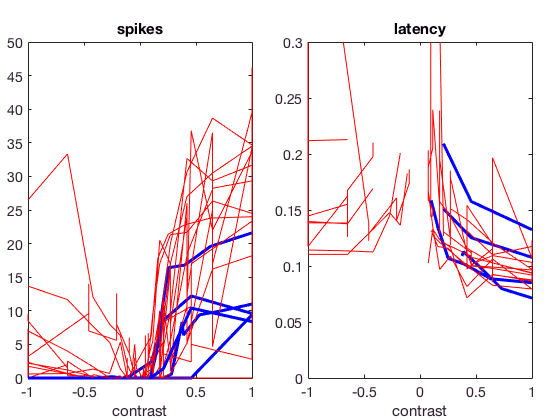

clf
h = tight_subplot(1,2, .1, .1, .05);


for ci = 1:size(dtab,1)
    
    if selectWfdsOn(ci)
        col = 'b';
        width = 3;
    elseif selectControl(ci)
        col = 'r';
        width = 1;
    end
    
    spotSize = dtab{ci, 'Contrast_contrastVal_ca'}{1};
    if ~isempty(spotSize)
        [spotSize, order] = sort(spotSize);
        spikes = dtab{ci, 'Contrast_onSpikes'}{1};
        spikes = spikes(order);
        
        axes(h(1))
        plot(spotSize, spikes, col, 'LineWidth',width);
        hold on
        xlabel('contrast')
        
        axes(h(2))
        lat = dtab{ci, 'Contrast_onLatency'}{1};
        lat = lat(order);
        plot(spotSize, lat, col, 'LineWidth',width);
        hold on
        xlabel('contrast')
        ylim([0,.3])
    end
end

title(h(1), 'spikes')
title(h(2),'latency')

## Contrast Responses averaged

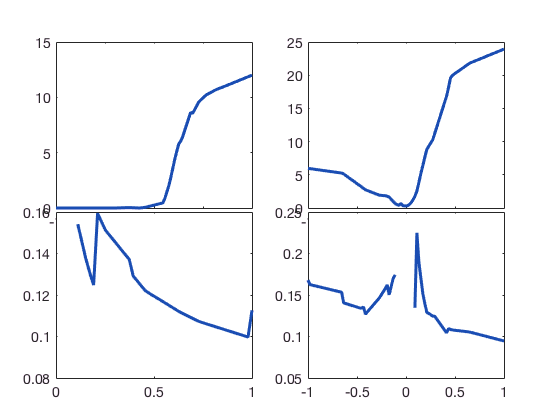

figure(102);clf;
peakSize = [];
tailSpikes = [];
spikesOverBaselineByVar = {};

varsToMean = {'Contrast_onSpikes','Contrast_onLatency'};
ylabels = {'spikes','sec'};
baselinesToMean = {'Contrast_contrastVal_ca','Contrast_contrastVal_ca'};

handles = tight_subplot(length(varsToMean), 2, [0.01, .1], 0.1, .1);
% tight_subplot(Nh, Nw, gap, marg_h, marg_w)

mean_contrast = linspace(-1,1);

for vari = 1:length(varsToMean)
    cellCount = 0;
    
    for cellTypeIndex = 1:2
        spikesOverSpotSize = [];
        
        selects = {selectWfdsOn, selectControl};
        
        for ci = 1:numCells
            sel = selects{cellTypeIndex};
            if ~sel(ci)
                continue
            end
            spotSize = dtab{ci, baselinesToMean{vari}}{1};
            
            if ~isempty(spotSize)
                cellCount = cellCount + 1;
                spikes = dtab{ci, varsToMean{vari}}{1};
                % make mean spikes for each size due to repeat epochs
                unique_sizes = unique(spotSize);
                averagedOverRepeats = zeros(size(unique_sizes));
                for si = 1:length(unique_sizes)
                    averagedOverRepeats(si) = mean(spikes(spotSize == unique_sizes(si)));
                end
                       
        %         hold on
        %         plot(spotSize, spikes);
                [maxx, mi] = max(spikes);
                peakSize(ci) = spotSize(mi);
                tailSpikes(ci) = mean(spikes(end-2:end));
                
                % add to average
                spikesOverSpotSize(end+1,:) = interp1(unique_sizes, averagedOverRepeats, mean_contrast);
            end
        end
        spikesOverBaselineByVar{cellTypeIndex, vari} = spikesOverSpotSize;
    
        i = (vari-1) * 2 + cellTypeIndex;
        axes(handles(i));
        m = nanmean(spikesOverBaselineByVar{cellTypeIndex, vari});
        s = nanstd(spikesOverBaselineByVar{cellTypeIndex, vari}) / sqrt(cellCount);
        plot(mean_contrast, m, 'r', 'LineWidth',3, 'Color', colo)
%         hold on
%         plot(mean_spotSize, m+s, '--', 'Color', colo)
%         plot(mean_spotSize, m-s, '--', 'Color', colo)
%         line([0,1200],[0,0],'Color','k')
%         
%         if vari < length(varsToMean)
%             xticks([])
%         end
%         
%         [~, i] = max(abs(m));
%         mx = m(i);
%         if ~isnan(mx)
%             yticks(sort([0, round(mx)]))
%         end
%         
%         xlim([0,1200])
%         
%         ylabel(ylabels{vari})
%         cellTs = {'On','Off'};
%         if vari == 1
%             title(sprintf('%s', cellTs{cellTypeIndex}))
%         end
%         if vari == length(varsToMean)
%             xlabel('Spot diameter (µm)')
%         end
                   
        hold off
    end
end

## SPEED /  DEPENDENT DS Index

figure(105);clf;

handles = tight_subplot(1,2, .0, [.13, .08], .1);

% DSI over Speed
axes(handles(1));
for i = 1:numCells
    if selectControl(i)
        continue
    end
    if selectWfdsOn(i)
        c = colo;
        x = 0;
    else
        c = colo2;
        x = 50;
    end
    plot([250, 500, 1000]+x,dtab{i,{'MB_250_DSI_sp', 'MB_500_DSI_sp', 'MB_1000_DSI_sp'}},...
        '+-', 'Color', c, 'MarkerSize',10)
    hold on
end
xlim([100,1150])
ylim([0,.7])
xlabel('Movement speed (µm/sec)')
ylabel('DSI')

plot([250, 500, 1000], nanmean(dtab{selectWfdsOn,{'MB_250_DSI_sp', 'MB_500_DSI_sp', 'MB_1000_DSI_sp'}}),'o-r','LineWidth',2);
plot([250, 500, 1000]+50, nanmean(dtab{selectWfdsOff,{'MB_250_DSI_sp', 'MB_500_DSI_sp', 'MB_1000_DSI_sp'}}),'o-r','LineWidth',2);

% title('Moving Bar DSI Speed Dependence')

axes(handles(2))
d1 = dtab{selectWfdsOn, 'DrifTex_DSI_sp'};
x = 0*ones(length(d1), 1);
plot(x,d1, '+', 'Color', colo, 'MarkerSize',10)
hold on
d2 = dtab{selectWfdsOff, 'DrifTex_DSI_sp'};
x = 0*ones(length(d2), 1) + .1;
plot(x,d2, '+', 'Color', colo2, 'MarkerSize',10)
ylim([0,.7])
yticks([])

d3 = dtab{selectWfdsOn, 'DrifGrat_DSI_sp'};
x = 1*ones(length(d3), 1);
plot(x,d3, '+', 'Color', colo, 'MarkerSize',10)

d4 = dtab{selectWfdsOff, 'DrifGrat_DSI_sp'};
x = 1*ones(length(d4), 1) + .1;
plot(x,d4, '+', 'Color', colo2, 'MarkerSize',10)

ylim([0,.7])
yticks([])
xlim([-.5, 1.5])
xticks([0,1])
xticklabels({'Texture','Grating'})

plot([0, .1,1, 1.1], [nanmean(d1),nanmean(d2),nanmean(d3), nanmean(d4)],'or','LineWidth',2);


% Which stimulus is best for each cell's DSI
% axes(handles(2))
% boxplot(dtab{selectWfds,'best_DSI_sp'}, dtab{selectWfds,'best_source'},...
%     'GroupOrder',{'MB_250_DSI_sp','MB_500_DSI_sp','MB_1000_DSI_sp','DrifTex_DSI_sp','DrifGrat_DSI_sp'},...
%     'Labels',{'MB 250','MB 500','MB 1000','Texture','Grating'},...
%     'Colors',colo, 'LabelOrientation','inline')
% ylabel('DSI')
% title('Pop. DSI for Several Stimuli')

% axes(handles(2))
% vars = {'MB_250_DSI_sp','MB_500_DSI_sp','MB_1000_DSI_sp','DrifTex_DSI_sp','DrifGrat_DSI_sp'};
% dsiByStim = {};
% for vi = 1:length(vars)
%     dsi = dtab{:,vars{vi}};
%     dsi(isnan(dsi)) = [];
%     dsiByStim{vi} = dsi;
% end
% 
% distributionPlot(dsiByStim, 'color', colo);
% xticklabels({'MB 250','MB 500','MB 1000','Texture','Grating'});
% ax = gca;
% ax.XTickLabelRotation = 90;
% title('Population DSI for Various Stimuli')
% y = linspace(0,1,5);
% yticks(y)
% yticklabels('auto')
% ylabel('DSI')


## SPEED DEPENDENT DS Variance

figure(105);clf;

handles = tight_subplot(1,2, .0, [.13, .08], .1);

% DVar over Speed
axes(handles(1));
for i = 1:numCells
    if selectControl(i)
        continue
    end
    if selectWfdsOn(i)
        c = colo;
        x = 0;
    else
        c = colo2;
        x = 50;
    end
    plot([250, 500, 1000]+x,dtab{i,{'MB_250_DVar_sp', 'MB_500_DVar_sp', 'MB_1000_DVar_sp'}},...
        '+-', 'Color', c, 'MarkerSize',10)
    hold on
end
xlim([100,1150])
ylim([0,1])
xlabel('Movement speed (µm/sec)')
ylabel('DVar')

plot([250, 500, 1000], nanmean(dtab{selectWfdsOn,{'MB_250_DVar_sp', 'MB_500_DVar_sp', 'MB_1000_DVar_sp'}}),'o-r','LineWidth',2);
plot([250, 500, 1000]+50, nanmean(dtab{selectWfdsOff,{'MB_250_DVar_sp', 'MB_500_DVar_sp', 'MB_1000_DVar_sp'}}),'o-r','LineWidth',2);

% title('Moving Bar DVar Speed Dependence')

axes(handles(2))
d1 = dtab{selectWfdsOn, 'DrifTex_DVar_sp'};
x = 0*ones(length(d1), 1);
plot(x,d1, '+', 'Color', colo, 'MarkerSize',10)
hold on
d2 = dtab{selectWfdsOff, 'DrifTex_DVar_sp'};
x = 0*ones(length(d2), 1) + .1;
plot(x,d2, '+', 'Color', colo2, 'MarkerSize',10)
ylim([0,.7])
yticks([])

d3 = dtab{selectWfdsOn, 'DrifGrat_DVar_sp'};
x = 1*ones(length(d3), 1);
plot(x,d3, '+', 'Color', colo, 'MarkerSize',10)

d4 = dtab{selectWfdsOff, 'DrifGrat_DVar_sp'};
x = 1*ones(length(d4), 1) + .1;
plot(x,d4, '+', 'Color', colo2, 'MarkerSize',10)

ylim([0,1])
yticks([])
xlim([-.5, 1.5])
xticks([0,1])
xticklabels({'Texture','Grating'})

plot([0, .1,1, 1.1], [nanmean(d1),nanmean(d2),nanmean(d3), nanmean(d4)],'or','LineWidth',2);


## Example polar plots

figure(106);clf;

handles = tight_subplot(1,5, .02, .0, .01);
load('analysisTrees/automaticData/polarPlotsByStimForExampleCell');
plotNames = {'MB 500','MB 1000','MB 2000','Tex 1000','Gratings'};

% polarPlots{1,2} = nodeData.ONSETspikes.mean;
% polarPlots{1,1} = nodeData.barAngle;
% polarPlots{3,1} = nodeData.barAngle;
% polarPlots{4,1} = nodeData.textureAngle;
% polarPlots{4,2} = nodeData.spikeCount_stimAfter500ms.mean;
% polarPlots{5,1} = nodeData.gratingAngle;
% polarPlots{5,2} = nodeData.F1amplitude.value;


for si = 1:length(plotNames)
    axes(handles(si));
    
    polarplotImproved(polarPlots{si,1}, polarPlots{si,2});
    thetaticklabels([])
    
    if si > 4
        rticklabels([])
    end

    if strcmp(plotNames{si}, 'Gratings')
        title(sprintf('%s F1 Amp', plotNames{si}));
    else
        title(sprintf('%s Spike Count', plotNames{si}));
    end
end


## another polar set


figure(108);clf;

% load('analysisTrees/automaticData/polarPlotsByStimForExampleCell2');
plotNames = {'MB 250','MB 500','MB 1000','MB 2000'};
handles = tight_subplot(1,length(plotNames), .02, .0, .01);


% polarPlots{1,2} = nodeData.ONSETspikes.mean;
% polarPlots{1,1} = nodeData.barAngle;
% polarPlots{3,1} = nodeData.barAngle;
% polarPlots{4,1} = nodeData.textureAngle;
% polarPlots{4,2} = nodeData.spikeCount_stimAfter500ms.mean;
% polarPlots{5,1} = nodeData.gratingAngle;
% polarPlots{5,2} = nodeData.F1amplitude.value;


for si = 1:length(plotNames)
    axes(handles(si));
    
    polarplotImproved(polarPlots{si,1}, polarPlots{si,2});
    thetaticklabels([])
    
    if si > 4
        rticklabels([])
    end

    if strcmp(plotNames{si}, 'Gratings')
        title(sprintf('%s F1 Amp', plotNames{si}));
    else
        title(sprintf('%s Spike Count', plotNames{si}));
    end
end

## Sample drifting grating responses

figure(199);clf;

cellName = '092816Bc5';
epochs = 117:128;
t = 0:.0001:5.4999;


% cellName = '032416Ac2';
% epochs = 141:(141+11);
% t = 0:.0001:6.4999;


global CELL_DATA_FOLDER
load([CELL_DATA_FOLDER filesep cellName])
%
angles = [];
handles = tight_subplot(length(epochs), 1, .02, .1);

for hi = 1:length(epochs)
    epoch = cellData.epochs(epochs(hi));
    angles(hi) = epoch.get('textureAngle');
end

[angles,i] = sort(angles);
epochs = epochs(i);

for hi = 1:length(epochs)
    axes(handles(hi));
    epoch = cellData.epochs(epochs(hi));
    r = epoch.getData() - mean(epoch.getData());
    plot(t, r);
    if angles(hi) == 210
        s = '("Preferred")';
    elseif angles(hi) == 60
        s = '("Null")';
    else
        s = '';
    end
%     title(sprintf('Movement Direction: %g deg %s', angles(hi), s))
    yticks([])
    if hi < 12
        xticks([])
    else
        xlabel('Time (sec)');
    end
end
    
linkaxes(handles)
xlim(handles(1), [0,5.5])
ylim([-120,40])

## WHOLE CELL DATA

% EI maps





% example gratings

load analysisTrees/automaticData/exampleGratings010716Ac1
figure(111);clf;
polarplotImproved(exampleGratings010716Ac1{1},exampleGratings010716Ac1{2})

## LOCATION DATA

figure(141);clf
ha = tight_subplot(1,3, .05, .05, .05);



map_data = dtab{selectWfds, {'location_x','location_y','best_DSang_sp','best_DSI_sp','eye','imageAngle'}};

% map_data: X, Y, angle, DSI, right=1
map_data(map_data(:,1) == 0 & map_data(:,2) == 0, :) = [];

x = -1*map_data(:,1)/1000; % compensate for rig spatial flip in dimension (negative right)
y = map_data(:,2)/1000;
ang = map_data(:,3);
mag = map_data(:,4);
left = map_data(:,5) == -1;
right = map_data(:,5) == 1;
u = mag .* cosd(ang);
v = mag .* sind(ang);


theta = linspace(0, 2*pi);
circx = cos(theta)*2;
circy = sin(theta)*2;

% axes(ha(1))
% plot(x, y,'o', 'Color', colo)
% line([-100,100],[0,0])
% line([0,0],[-100,100])
% axis(1.2*[-2000,2000, -2000,2000])
% axis square
% title('all wfds locations')

% Together
axes(ha(1));
x_eyesTogether = x;
x_eyesTogether(right) = -1 * x_eyesTogether(right);
uRigFlipped = u;
uRigFlipped(right) = -1 * uRigFlipped(right);
sel = left == 1;
quiver(x_eyesTogether(sel),y(sel),uRigFlipped(sel),v(sel),1.3,'color',colo2,'linewidth',2)
hold on
sel = right == 1;
quiver(x_eyesTogether(sel),y(sel),uRigFlipped(sel),v(sel),1.3,'color',colo,'linewidth',2)
plot(circx, circy, '--k')
legend('left','right');
line([-.500, .500],[0,0],'color','k')
line([0,0],[-.500, .500],'color','k')
axis(1.2*[-2,2, -2,2])
axis square
title('Both eyes (Right X Flipped)')
xlabel('Nasal -- Caudal')

% left
axes(ha(2));
sel = left == 1;
quiver(x(sel),y(sel),u(sel),v(sel),1.3,'linewidth',2, 'Color', colo2)
hold on
plot(circx, circy, '--k')
line([-.500, .500],[0,0],'color','k')
line([0,0],[-.500, .500],'color','k')
axis(1.2*[-2,2, -2,2])
axis square
title('Left Eye')
xlabel('Nasal -- Caudal')

% right
axes(ha(3));
sel = right == 1;
quiver(x(sel),y(sel),u(sel),v(sel),1.3,'linewidth',2, 'Color', colo)
hold on
plot(circx, circy, '--k')
line([-.500, .500],[0,0],'color','k')
line([0,0],[-.500, .500],'color','k')
axis(1.2*[-2,2, -2,2])
axis square
title('Right Eye')
xlabel('Caudal -- Nasal')


% % Image angle
% ang = map_data(:,6);
% u = cosd(ang);
% v = sind(ang);
% axes(ha(5));
% quiver(x,y,u,v, 'Color', colo,'linewidth',2)
% title('image angles')
% axis(1.2*[-2000,2000, -2000,2000])
% axis square
% 
% % Autocenter offset angle
% ang = rad2deg(autocenterOffsetDirections(selectWfds));
% u = autocenterOffsetDistance(selectWfds) .* cosd(ang);
% v = autocenterOffsetDistance(selectWfds) .* sind(ang);
% axes(ha(6));
% quiver(x,y,u,v,2, 'Color', colo,'linewidth',2)
% title('autocenter offset angles')
% axis(1.2*[-2000,2000, -2000,2000])
% axis square

## autocenter data

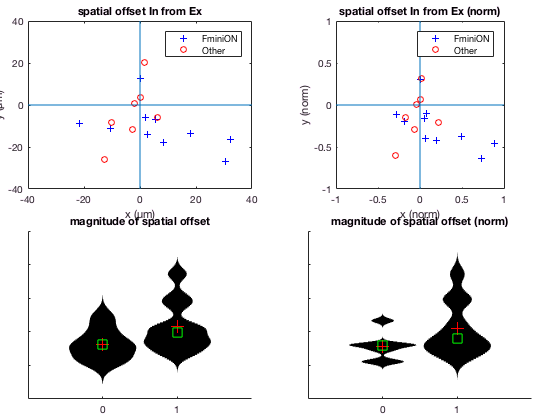

figure(131);clf;
handles = tight_subplot(2,2, .1, .05, .05);
% angleOffset = zeros(length(cellNames),1);
% for i = 1:length(cellNames)
%     if ~isempty(strfind(cellNames{i}, 'B'))
%         angleOffset(i) = 270;
%     else
%         angleOffset(i) = 180;
%     end
% end
% angleOffset = deg2rad(angleOffset);

diffX = dtab.spatial_in_centerX - dtab.spatial_ex_centerX;
diffY = dtab.spatial_in_centerY - dtab.spatial_ex_centerY;
avgSigma = mean(dtab{:,{'spatial_in_sigma2X','spatial_ex_sigma2X','spatial_in_sigma2Y','spatial_ex_sigma2Y'}}, 2);
autocenterOffsetDistance = sqrt(diffX.^2 + diffY.^2);
autocenterOffsetDistanceNormalized = autocenterOffsetDistance ./ avgSigma;
autocenterOffsetDirections = angle(diffX + sqrt(-1) * diffY);
dtab.spatial_exin_offset = autocenterOffsetDistance .* exp(sqrt(-1) * autocenterOffsetDirections);

axes(handles(1));
plot(autocenterOffsetDistance(selectWfdsOn) .* exp(sqrt(-1) * autocenterOffsetDirections(selectWfdsOn)), '+b')
hold on
plot(autocenterOffsetDistance(selectControl) .* exp(sqrt(-1) * autocenterOffsetDirections(selectControl)), 'or')
hold off
line([-1,1]*40,[0,0])
line([0,0],[-1,1]*40)
ylim([-40,40])
xlim([-40,40])
xlabel('x (µm)');
ylabel('y (µm)');
title('spatial offset In from Ex')
legend('FminiON','Other')

axes(handles(2));
plot(autocenterOffsetDistanceNormalized(selectWfdsOn) .* exp(sqrt(-1) * autocenterOffsetDirections(selectWfdsOn)), '+b')
hold on
plot(autocenterOffsetDistanceNormalized(selectControl) .* exp(sqrt(-1) * autocenterOffsetDirections(selectControl)), 'or')
hold off
line([-1,1],[0,0])
line([0,0],[-1,1])
ylim([-1,1])
xlim([-1,1])
xlabel('x (norm)');
ylabel('y (norm)');
axis square
title('spatial offset In from Ex (norm)')
legend('FminiON','Other')


axes(handles(3));
% boxplot(autocenterOffsetDistance, selectWfds, 'Labels',{'Control','FminiON'})
distributionPlot(autocenterOffsetDistance, 'groups', selectWfdsOn)
% hold on
% histogram(autocenterOffsetDistance(~selectWfds), 10)
% hold off
% xlim([-.5,1.5])
xlabel('type')
title('magnitude of spatial offset')
% legend('WFDS','Other')

axes(handles(4));
distributionPlot(autocenterOffsetDistanceNormalized, 'groups',selectWfdsOn)
title('magnitude of spatial offset (norm)')

figure(135);clf;

% axes(handles(5));
polarhistogram(autocenterOffsetDirections(selectWfds), linspace(0, 2*pi, 13), 'Normalization','pdf')
thetaticklabels([])
% hold on
% polarhistogram(autocenterOffsetDirections(~selectWfds), 10)
% hold off
% title('angle of spatial offset')

## Comparing autocenter to image and DS

figure(132);clf;
handles = tight_subplot(1,2, .05, .1, .1);

axes(handles(1));
spatialToTextureDiff = dtab.best_DSang_sp - rad2deg(autocenterOffsetDirections);
polarhistogram(deg2rad(spatialToTextureDiff(selectWfds)), 10)
% hold on
% polarhistogram(deg2rad(spatialToTextureDiff(~selectWfds)), 10)
title('difference between best angle and offset angle')

axes(handles(2));
spatialToImageDiff = mod(autocenterOffsetDirections(selectWfds) - dtab.imageAngle(selectWfds), 360);
polarhistogram(deg2rad(spatialToImageDiff), 10)
title('difference between image angle and offset angle')

## Compare offset to DSI with a fit line

figure(133);clf;
plot(autocenterOffsetDistanceNormalized(selectWfds), dtab{selectWfds,'best_DSI_sp'}, 'o')
title('Offset vs DSI')
xlabel('AC Offset Distance Normalized')
ylabel('DSI')
line([0,1],[0,0])
line([0,0],[0,.6])




## Plot an example light step and psth

clf;
handles = tight_subplot(2,1, .01, .15);
t = -0.5:.01:2;
axes(handles(1));
plot(t,PSTH, 'Color', colo)
yticks([])
xticks([])
yl = ylim();
c = rectangle('Position',[0,yl(1),1,diff(yl)],'FaceColor',[0.999, 0.999, .8],'LineStyle','none');
uistack(c,'bottom')

% load cellData/110216Ac19.mat
e = cellData.epochs(5);

t = -0.5:.0001:1.9999;
axes(handles(2));
plot(t, e.getData(), 'Color', colo)
xlabel('Time from light onset (sec)');
yticks([])

hold on
yl = ylim();
c = rectangle('Position',[0,yl(1),1,diff(yl)],'FaceColor',[0.999, 0.999, .8],'LineStyle','none');
uistack(c,'bottom')



## Compare parameterized light step values

paramNames = {'polarity','delay', 'rise dur', 'hold dur', 'decay time const', 'decay baseline/peak'};
paramColumns = dtab{:,{'LS_ON_params_ex','LS_ON_params_in'}};
paramMatrix = [];
for exin = 1:2
    for p = 1:length(paramColumns)
        par = paramColumns{p,exin};
        if isempty(par)
            par = nan*ones(1,6);
        end
        paramMatrix(p,exin,:) = par;
    end
    
    
    figure;clf;
    h = tight_subplot(3,2,.1);
    for parami = 1:size(allParams, 2)
        
        axes(h(parami));
        histogram(paramMatrix(selectWfdsOn,exin,parami),8)
        hold on
        histogram(paramMatrix(selectControl,exin,parami),8)
        title(paramNames{parami})
    end
end



## Compare delays

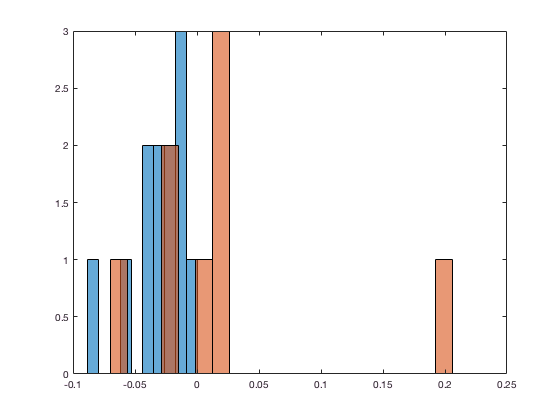

figure;
delayToPeak = paramMatrix(:,:,2) + paramMatrix(:,:,3);
delayDifference = diff(delayToPeak')';
histogram(delayToPeak(selectWfdsOn,1)-delayToPeak(selectWfdsOn,2), 10)
hold on
histogram(delayToPeak(selectControl,1)-delayToPeak(selectControl,2), 20)

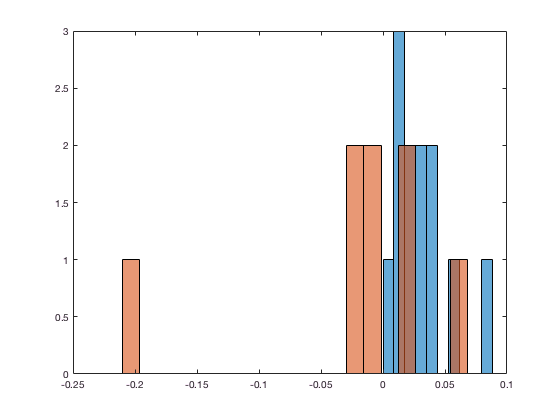


figure
histogram(delayDifference(selectWfdsOn),10)
hold on
histogram(delayDifference(selectControl),20)

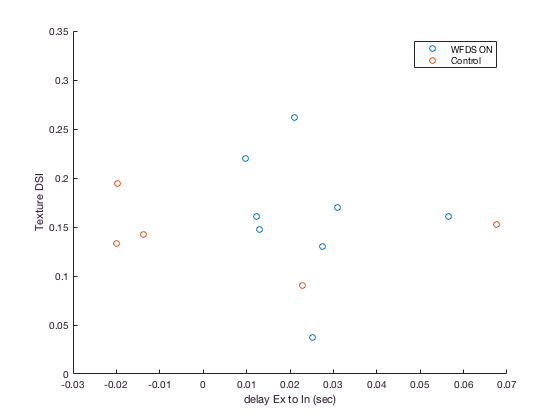


figure
hold on
plot(delayDifference(selectWfdsOn), dtab{selectWfdsOn,'DrifTex_DSI_sp'}, 'o')
plot(delayDifference(selectControl), dtab{selectControl,'DrifTex_DSI_sp'}, 'o')
xlabel('delay Ex to In (sec)')
ylabel('Texture DSI')
legend('WFDS ON','Control')
ylim([0,.35])

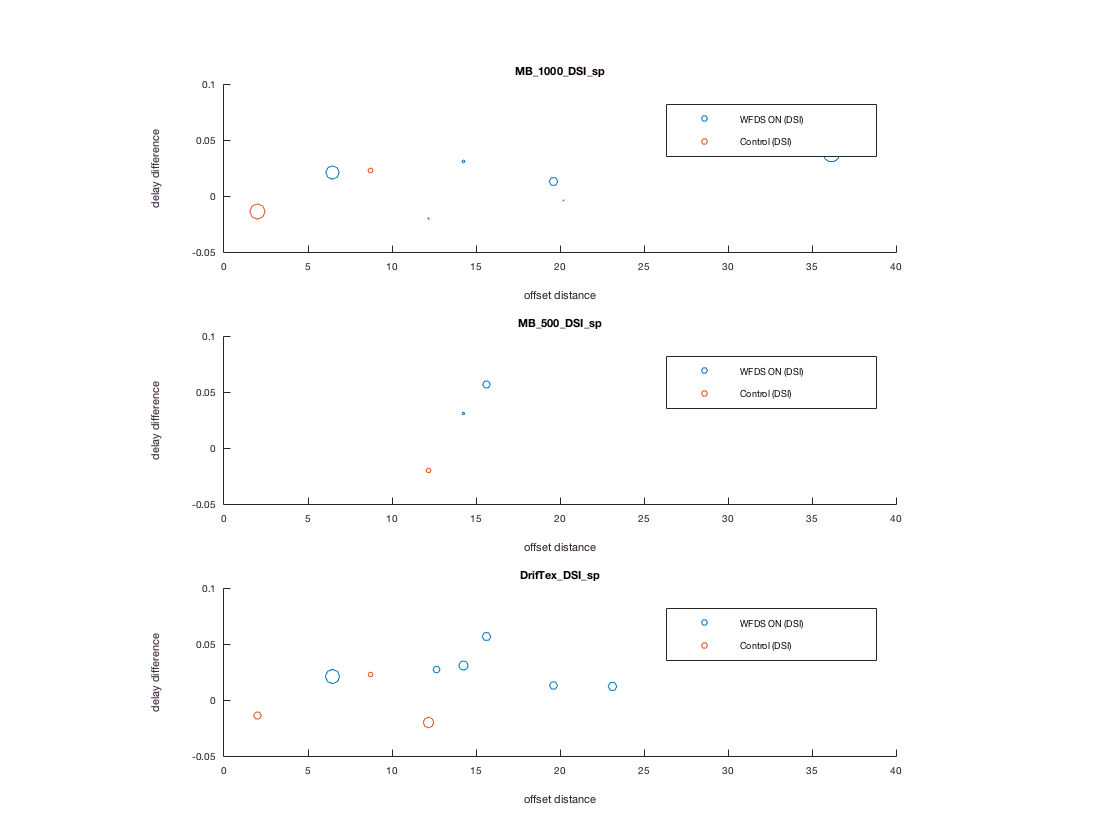

movingDataSets = {'MB_1000_DSI_sp','MB_500_DSI_sp','DrifTex_DSI_sp'};

figure
h = tight_subplot(length(movingDataSets),1,.1, .1, .2);

for mi = 1:length(movingDataSets)
    axes(h(mi))
    scatter(abs(dtab{selectWfdsOn,'spatial_exin_offset'}), delayDifference(selectWfdsOn), 3000*dtab{selectWfdsOn,movingDataSets{mi}}.^2)
    hold on
    scatter(abs(dtab{selectControl,'spatial_exin_offset'}), delayDifference(selectControl), 3000*dtab{selectControl,movingDataSets{mi}}.^2)
    
    ylim([-.05,.1])
    xlabel('offset distance')
    ylabel('delay difference')
    legend('WFDS ON (DSI)','Control (DSI)')
    title(movingDataSets{mi}, 'Interpreter','none');
end